# Industrial cutter process anomaly detection

#### Autoencoder-based anomaly detection

clear all;
load FeatureEntire.mat
idx = isinf(feature_All.("ch3_stats/Col1_THD"));
feature_All(idx, :) = [];

idx = cvpartition(feature_All.label, 'holdout', 0.1);
feature_train = feature_All(idx.training, :);
feature_val = feature_All(idx.test, :);

Setting training options for AutoEncoder


Xtemp = feature_train{feature_train.label=='After', 2:end};
for i = 1:length(Xtemp)
    X{i,:} = Xtemp(i,:);
end

layers = [ sequenceInputLayer(1, 'Name', 'in')
    bilstmLayer(16, 'Name', 'bilstm1')
    reluLayer('Name', 'relu1')
    bilstmLayer(32, 'Name', 'bilstm2')
    reluLayer('Name', 'relu2')
    bilstmLayer(16, 'Name', 'bilstm3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(1, 'Name', 'fc')
    regressionLayer('Name', 'out') ];
options = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 500,...
    'MaxEpochs',500);
% net = trainNetwork(X, X, layers, options);
load davidNet


Visualize encoder behavior

testNorm = {feature_val{1200, 2:end}};
testAbNorm = {feature_val{200, 2:end}};
decodedNorm = predict(net,testNorm);
decodedAbNorm = predict(net,testAbNorm);


tiledlayout(1, 3,'TileSpacing','none')
nexttile
plot(testNorm{:}), title('Normal Input'), hold on, plot(decodedNorm{:}), hold off, legend({'Input', 'Decoded'}), grid on
nexttile
plot(testAbNorm{:}),title('Abnormal Input'), hold on, plot(decodedAbNorm{:}), hold off, legend({'Input', 'Decoded'}), grid on
nexttile
plot(testNorm{:} - decodedNorm{:}), title('Error'), hold on, plot(testAbNorm{:} - decodedAbNorm{:}), hold off, legend({'Normal', 'Abnormal'}), grid on


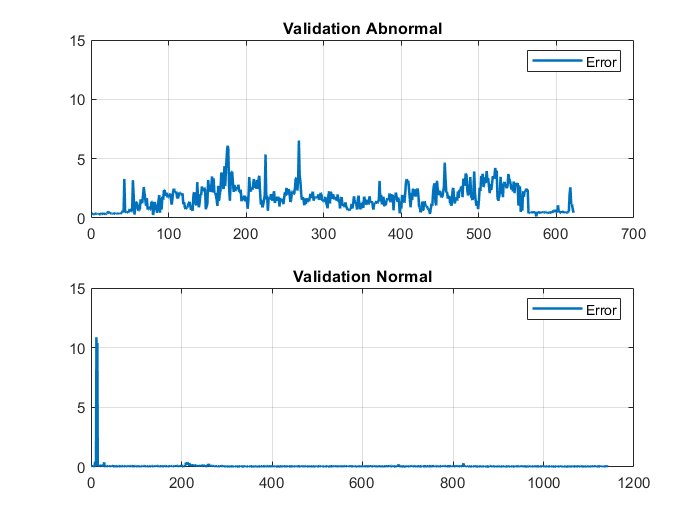

tmp_val = feature_val{feature_val.label=='Before', 2:end};
for i = 1:length(tmp_val)
    Xtmp_val{i,:} = tmp_val(i,:);
end
y_hat = predict(net, Xtmp_val);
for i = 1:length(tmp_val)
    E1(i,:) = sqrt(sum((y_hat{i} - Xtmp_val{i}).^2));
end
subplot(211), plot(1:length(E1), E1, 'LineWidth',1.5), legend('Error')
grid on, ylim([0 15]), title('Validation Abnormal')

tmp_val2 = feature_val{feature_val.label=='After', 2:end};
for i = 1:length(tmp_val2)
    Xtmp_val2{i,:} = tmp_val2(i,:);
end
y_hat2 = predict(net, Xtmp_val2);
for i = 1:length(tmp_val2)
    E2(i,:) = sqrt(sum((y_hat2{i} - Xtmp_val2{i}).^2));
end
subplot(212), plot(1:length(E2), E2, 'LineWidth',1.5), legend('Error')
grid on, ylim([0 15]), title('Validation Normal')

Validation accuracy for Anomaly detection using AutoEncoder

fprintf('Mean Error value for Abnormal dataset : %.2f\n', mean(E1))

Mean Error value for Abnormal dataset : 1.67


fprintf('Mean Error value for Normal dataset : %.2f', mean(E2))

Mean Error value for Normal dataset : 0.08

Accuracy for entire validation dataset

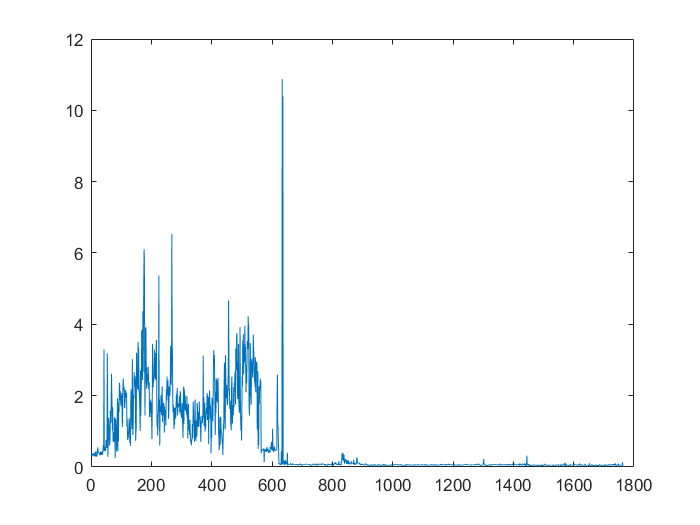

tmp_all = feature_val{:, 2:end};
for i = 1:length(tmp_all)
    Xtmp_val3{i,:} = tmp_all(i,:);
end
y_hat3 = predict(net, Xtmp_val3);
for i = 1:length(tmp_all)
    E3(i,:) = sqrt(sum((y_hat3{i} - Xtmp_val3{i}).^2));
end

predAE = E3'>0.3;
figure;
plot(E3)

predAE = categorical(predAE, [1, 0], {'Before', 'After'})';
acc = numel(find(feature_val.label == predAE))/length(predAE)*100

acc = 99.2063